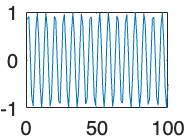

% making a plot out of time and sin of time
t = 1:100;
y = sin(t);
plot(t,y);

%playing a pure-tone signal at particular frequency, duration
%and sound-samplerate

s = 8000; % sampling rate
d = 0.8; % duration 
n = d*s; % number of samples
f = 440; % frequency in Hz
t = 1:n; 
tone = sin(2*pi*f*t/s);
sound(tone, s)

fA = input('Please specify frequency A: ');
fB = input ('Please specify frequency B: ');

[fHigh, fLow] = fHigherLower (fA, fB);

for i = 1:5
    PerformanceList(i) = RunTrial(fLow, fHigh);
end


%displaying the proportion 
correctAns = 0;
for i= 1:length(PerformanceList)
    correctAns = correctAns + PerformanceList(i);
end

proportion = correctAns / length(PerformanceList);
disp(['The proportion of correct answers is: ', num2str(proportion)]);






randomOrder = randperm(2);
if randomOrder(1)==1
    PlayTone(fLow);
    pause
    PlayTone(fHigh);
else
    PlayTone(fHigh);
    pause
    PlayTone(fLow);
end
response = input ('Which tone was lower frequency, first (1) or second (2)? ');

if response == randomOrder(1)
    isCorrect = 1;
else
    isCorrect = 0;
end


PerformanceList = [1 1 1 0 1 1];
correctAns = 0;
for i= 1:length(PerformanceList)
    correctAns = correctAns + PerformanceList(i);
end

proportion = correctAns / length(PerformanceList);

